# Ex03. Introduction to Signals and systems

### s1320112/ Motohisa YAMANO

## 1.1. Develop 4 descrete signal charts

This assignment involves plotting four discrete-time signals as specified in the problem set. The signals are defined using α = 0.5, with the index k ranging from -5 to 5 in increments of 1. To visualize these signals, the stem function was utilized. The specific signals analyzed are the unit step function x[n] = u[n] and the exponential signal h[n] = α^n u[n].

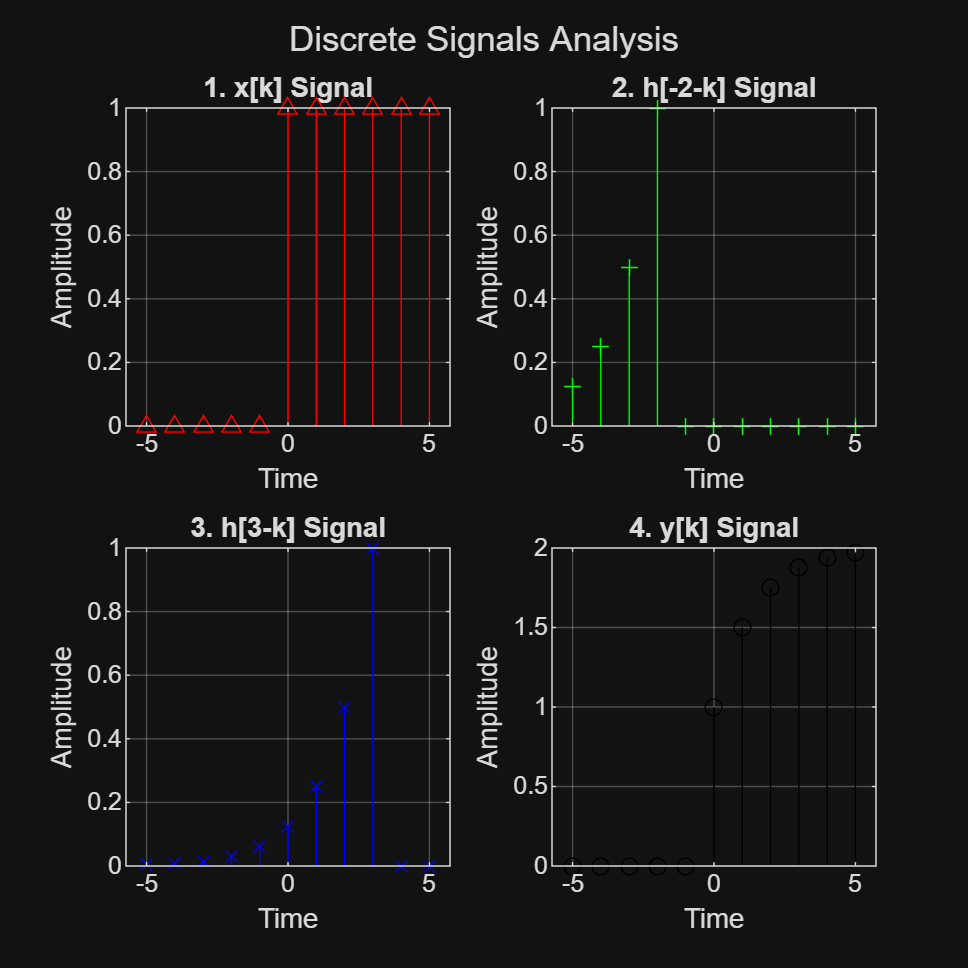

alpha = 0.5;
k = -5:5;
x = @(n) (n >= 0);
h = @(n) (alpha.^n) .* (n >= 0);
y = @(n) ((1 - alpha.^(n+1))/(1 - alpha)) .* (n >= 0);

figure('Position', [100, 100, 600, 600]);

subplot(2, 2, 1);
    p1 = stem(k, x(k));
    title('1. x[k] Signal');
    xlabel("Time");
    ylabel("Amplitude");
    set(p1, 'Color', 'r');
    set(p1, 'Marker', '^');
    grid on;

subplot(2, 2, 2);
    p2 = stem(k, h(-2-k));
    title('2. h[-2-k] Signal');
    xlabel("Time");
    ylabel("Amplitude");
    set(p2, 'Color', 'g');
    set(p2, 'Marker', '+');
    grid on;

subplot(2, 2, 3);
    p3 = stem(k, h(3-k));
    title('3. h[3-k] Signal');
    xlabel("Time");
    ylabel("Amplitude");
    set(p3, 'Color', 'b');
    set(p3, 'Marker', 'x');
    grid on;

subplot(2, 2, 4);
    p4 = stem(k, y(k));
    title('4. y[k] Signal');
    xlabel("Time");
    ylabel("Amplitude");
    set(p4, 'Color', 'k');
    set(p4, 'Marker', 'o');
    grid on;

%% Below is the 4 charts required in the assignemnt.
%% heaviside function mainly supports to express continuous signal, not discrete signal.
%% (In the case of x[k], it returns 0.5 at time 0 which is not the result of an ideal step function)
%% Then, I used (n >= 0) as a substitute for that. 
sgtitle('Discrete Signals Analysis'); 

## 1.2. Math Problem 

Below is the snapshot of my answer in fill-blank math problem.